clc;
clear;
close all;

## 添加路径

addpath('plane wave\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;
beamAmp=1;
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# MLA

rate=(0.15/40);%采样率（global）
rla1=-1.1;% 透镜1的曲率半径  
N=[27 41 51 71];%微透镜单元采样点数
d = N*rate;% 透镜单元边长
focallen=75;
beamSize=3;



beamStd=beamSize/2.85;
num=beamStd./d*5;%数量
area1 = mean(num.*d);%光场的面积
n=round(area1/rate);
t = 1.2;%透镜厚度
material={"F_SILICA"};
area3=12.8;
distance1 = 0:0.1:3;   % 投影距离

# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=1;%
T=100;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(route/rate)+n,n]);

Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
area1= single(area1);
area3= single(area3);

if canUseGPU
    
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    area1= gpuArray(area1);
    area3= gpuArray(area3);
end


u=zeros(length(N),length(distance1));
sigma=u;
fn=zeros(1,length(N));
B=u;
N_percent=u;

beam=GaussianBeam(beamAmp,beamStd,lambda);
beams=GaussianBeam.defocused(beam,10,n,rate);


# Fourier Lens

area2=13;
area=[area1,area1,area2,area3];
Dfl = area2;              %采样区域
%file='OLD2440-T2M(JCOPTIX-F=74.9胶合).txt';
FL=Lens(75);
%% 生成傅里叶透镜厚度函数
Lens.lensPhase_paraxial(FL,Dfl,rate,lambda);
Lens.lensSingle(FL);
%%生成匀光微透镜阵列厚度函数
if canUseGPU
    Lens.lensGPUArray(FL)
end

for kk=1:length(N)
MLA1=Lens([rla1,inf],t,d(kk),material,lambda);
MLA2=Lens([inf,-rla1],t,d(kk),material,lambda);
Lens.lensArrayThickFcn(MLA1,N(kk),num(kk),'square');
Lens.lensArrayThickFcn(MLA2,N(kk),num(kk),'square');
Lens.lensSingle(MLA1)
Lens.lensSingle(MLA2)
if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(MLA2)
end
lensgroup={MLA1,MLA2,FL};
fn(kk)=fresnelnum(MLA1,lambda);
for jj=1:length(distance1)
I=zeros(round(area3/rate));
distance=[20,distance1(jj),focallen,focallen];


## 光场变换

tic
for ii=1:times
    %叠加随机相位
    beamss=GaussianBeam.beamNoise(beams,0.05,0);
    F = transform(beamss, area1, lambda, 20, [rate, rate]);
    index=round((velocity*(ii-1)*deltat)/rate+1);
    F=F.*phase(index:index+size(F,1)-1,:);
    F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);

    I_now=abs(F).^2;
    I = I+I_now;

    Inorm=imnorm(I);
    subplot(12,10,[1,90])
    imshow(uint16(Inorm*65536),mymap)
    
    Inorm=gather(Inorm);

    subplot(12,10,[91,100])
    progressBar([100,1000],ii/times)
    drawnow
end

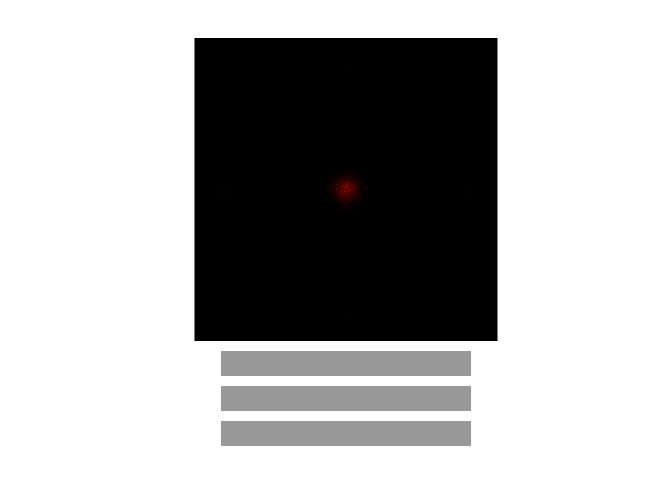

imwrite(Inorm,['Dis\Dis=' num2str(distance1(jj)) 'FN=' num2str(fn(kk)) '.bmp'])
subplot(12,10,101:110)
progressBar([100,1000],jj/length(distance1))
[u(kk,jj),sigma(kk,jj),N_percent(kk,jj)]=homoanalyse(Inorm);
end
subplot(12,10,111:120)
progressBar([100,1000],kk/length(N))
end

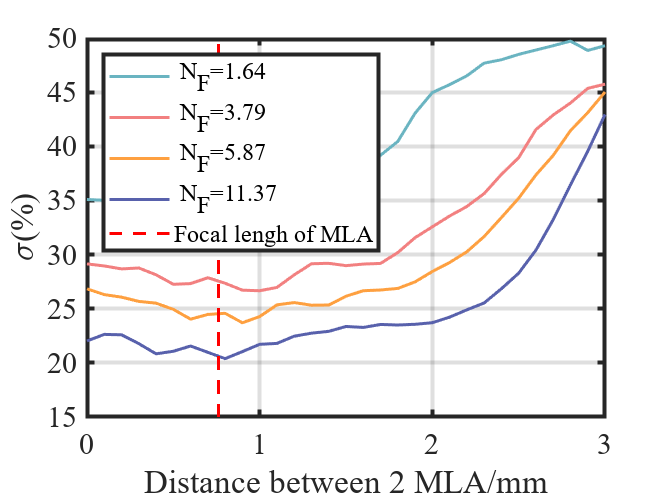

load('E:\File\Matlab\资料\color.mat');

figure
colororder(flip([color1;color2;color3;color4],1))
plot(distance1,sigma(1,:),distance1,sigma(2,:), ...
    distance1,sigma(3,:),distance1,sigma(4,:),...
    'LineWidth',1.5)
hold on
plot([focalLength(MLA1)-2*MLA1.thickness/MLA1.n_curwl, ...
    focalLength(MLA1)-2*MLA1.thickness/MLA1.n_curwl],[15,50] ...
 ,'LineWidth',1.5,'LineStyle','--','color','r')
set(gca,'LineWidth',2,'fontname','Times New Roman','Fontsize',15)
xlabel('Distance between 2 MLA/mm')
ylabel('\sigma(%)')
legend(['\it N_F=\rm' num2str(fn(1),'%.2f')],['\it N_F=\rm' num2str(fn(2),'%.2f')], ...
    ['\it N_F=\rm' num2str(fn(3),'%.2f')],['\it N_F=\rm' num2str(fn(4),'%.2f')], ...
    'Focal lengh of MLA','location','northwest','fontsize',12)
ylim([15,50])
grid on

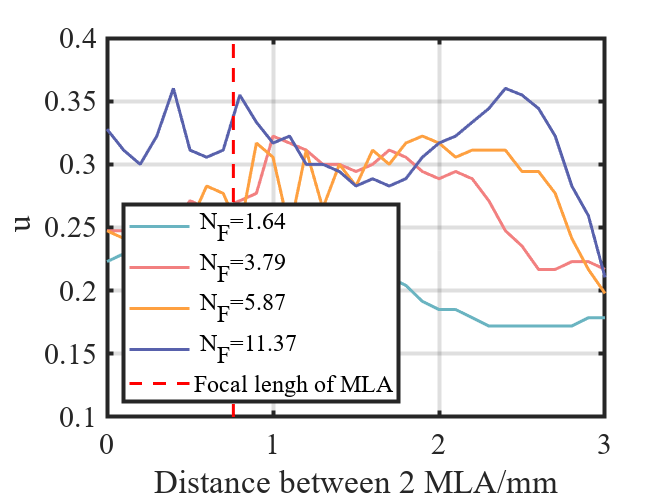

figure
colororder(flip([color1;color2;color3;color4],1))
plot(distance1,u(1,:),distance1,u(2,:), ...
    distance1,u(3,:),distance1,u(4,:),...
    'LineWidth',1.5)
hold on
plot([focalLength(MLA1)-2*MLA1.thickness/MLA1.n_curwl ...
    ,focalLength(MLA1)-2*MLA1.thickness/MLA1.n_curwl],[0.1,0.4] ...
 ,'LineWidth',1.5,'LineStyle','--','color','r')
set(gca,'LineWidth',2,'fontname','Times New Roman','Fontsize',15)
xlabel('Distance between 2 MLA/mm')
ylabel('\it u')
legend(['\it N_F=\rm' num2str(fn(1),'%.2f')],['\it N_F=\rm' num2str(fn(2),'%.2f')], ...
    ['\it N_F=\rm' num2str(fn(3),'%.2f')],['\it N_F=\rm' num2str(fn(4),'%.2f')], ...
    'Focal lengh of MLA','location','southwest','fontsize',12)
ylim([0.1,0.4])
grid on

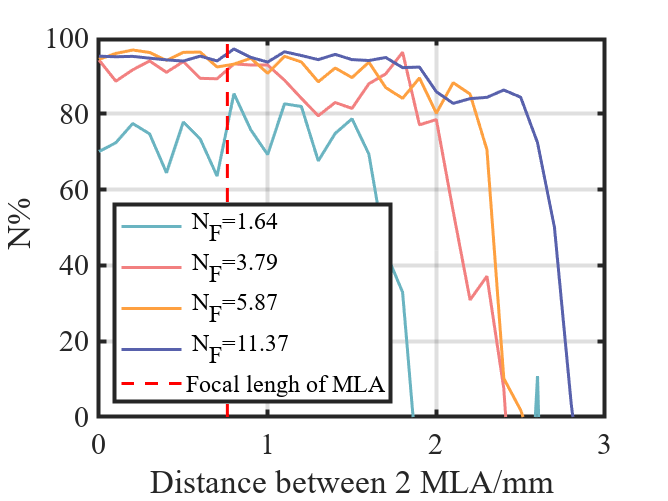

figure
colororder(flip([color1;color2;color3;color4],1))
plot(distance1,N_percent(1,:),distance1,N_percent(2,:), ...
    distance1,N_percent(3,:),distance1,N_percent(4,:),...
    'LineWidth',1.5)
hold on
plot([focalLength(MLA1)-2*MLA1.thickness/MLA1.n_curwl ...
    ,focalLength(MLA1)-2*MLA1.thickness/MLA1.n_curwl],[0,100] ...
 ,'LineWidth',1.5,'LineStyle','--','color','r')
set(gca,'LineWidth',2,'fontname','Times New Roman','Fontsize',15)
xlabel('Distance between 2 MLA/mm')
ylabel('\it N%')
legend(['\it N_F=\rm' num2str(fn(1),'%.2f')],['\it N_F=\rm' num2str(fn(2),'%.2f')], ...
    ['\it N_F=\rm' num2str(fn(3),'%.2f')],['\it N_F=\rm' num2str(fn(4),'%.2f')], ...
    'Focal lengh of MLA','location','southwest','fontsize',12)
ylim([0,100])
grid on